# PART 2

## Section 1


% % Call function to do a window_size for 0, 10, 50, 100.
% [raw, time] = wind_size(0);
% [win_10,time_10] = wind_size(10);
% [win_50,time_50] = wind_size(50);
% [win_100,time_100] = wind_size(100);
% 
% % Plot all values
% figure(1)
% plot(time,raw)
% hold on
% plot(time_10,win_10, 'r')
% hold on
% plot(time_50,win_50, 'g')
% hold on
% plot(time_100,win_100, 'k')
% 
% % Include labels
% legend('Z raw','Window size = 10','Window size = 50','Window size = 100')
% ylabel('Acceleration (g)')
% xlabel('Time (m/s)')



## Section 2

data = csvread('z_flip_data.csv');
z_data = data(:,2);
time = data(:,1)/1000;

Fs = 1/mean(diff(time))

Fs = 73.8049

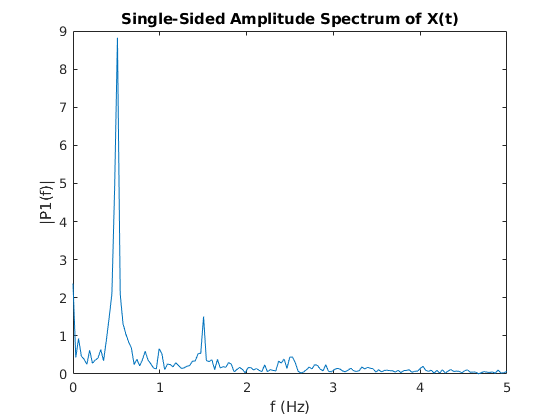

T = 1/Fs;             % Sampling period       
L = size(z_data,1);             % Length of signal
% t = (09:L-1)*T;        % Time vector
t = time;

Y = fft(z_data);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

figure(2)
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
xlim([0 5]) %fits axis so that peak x-values are identifiable
ylabel('|P1(f)|')

function [val, time] = wind_size(n)
    %% Prepare data and filter settings
    % Set the window size. 
    %%%%% You will need to change this! %%%%%
    window_size = n;
    
    % Import the data we've generated. You can find this file on Canvas.
    data = csvread('z_flip_data.csv');
    
    % Separate the data:
    % Raw signal
    z_raw = data(:, 2);
    % Time, converted to s
    
    time = data(:, 1) ./ 1000;

    if window_size == 0
        val = z_raw;
        
    else
            % Quick sanity check to avoid improper window size settings
        if window_size > length(z_raw)
            disp('Your window size is bigger than the whole dataset!')
        	return;
        end
        
        % Create the array that will hold the filtered values
        z_filtered = zeros(1, length(z_raw) - window_size + 1);
        
        %% Run the moving average filter
        % Like a real-time filter, this will be front-biased. That means it will
        % take the average of the most recent n (window size) datapoints. 
        
        % Loop through the data, gathering the averages
        % i represents the front of the window (newest data in filter)
        for f = window_size:length(z_raw)
            % Find the back of the window (oldest data in filter)
            b = f - window_size + 1;
            % We can also use b as the index for our filtered data    
        	z_filtered(b) = mean(z_raw(b:f));
            % Within z_raw(b:f), there should always be n (window size) datapoints
        end
        time = time(1:end-(n-1));
        val = z_filtered;
    end

   
end

